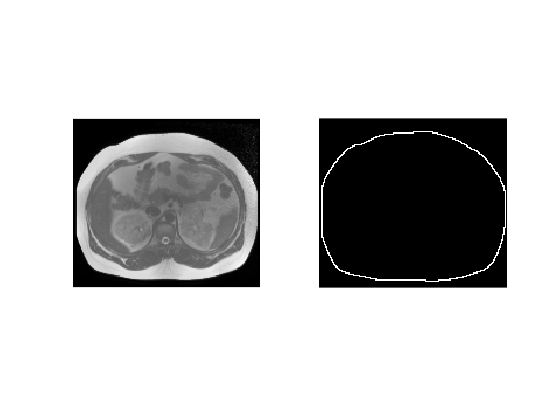

%Load the dataset and show the images with their segmentations
data1 = load("dataForNN_foreBorder_clip0.mat");
data2 = load("dataForNN_foreBorder_clip1.mat");
data3 = load("dataForNN_inside_clip0.mat");

figure();
subplot(1, 2, 1), imshow(data1.trainingImage);
subplot(1, 2, 2), imshow(data1.trainingSegmentation);

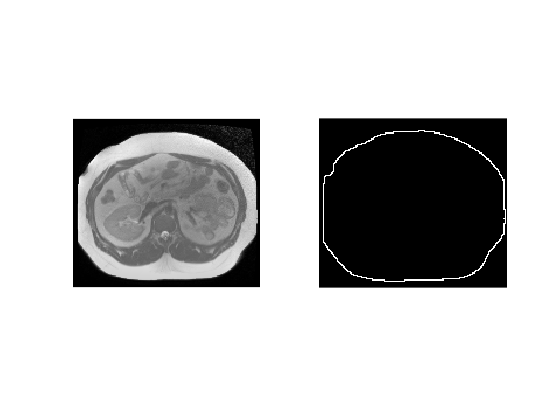


figure();
subplot(1, 2, 1), imshow(data1.testImage, []);
subplot(1, 2, 2), imshow(data1.testSegmentation, []);

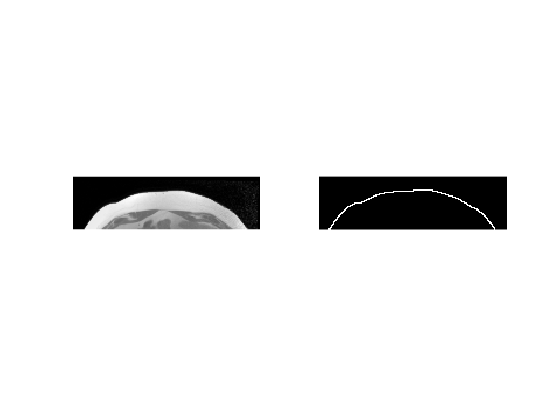



figure();
subplot(1, 2, 1), imshow(data2.trainingImage, []);
subplot(1, 2, 2), imshow(data2.trainingSegmentation, []);

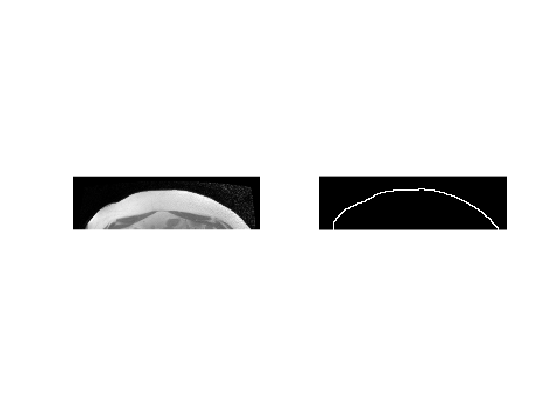


figure();
subplot(1, 2, 1), imshow(data2.testImage, []);
subplot(1, 2, 2), imshow(data2.testSegmentation, []);

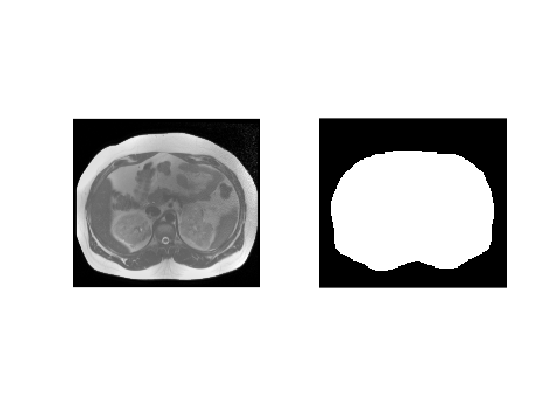


figure();
subplot(1, 2, 1), imshow(data3.trainingImage, []);
subplot(1, 2, 2), imshow(data3.trainingSegmentation, []);

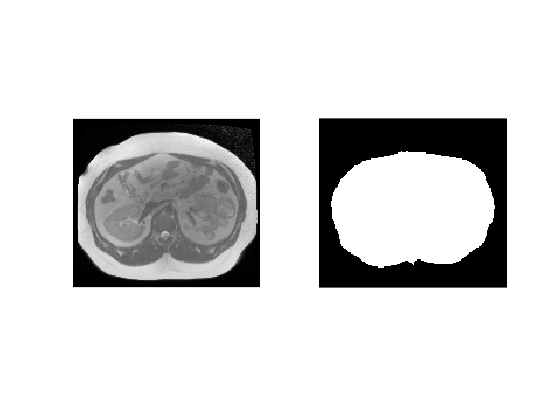


figure();
subplot(1, 2, 1), imshow(data3.testImage, []);
subplot(1, 2, 2), imshow(data3.testSegmentation, []);

%Define Beta vector, cost vector, stepsize and the training/testing image
Beta = zeros([1, 6]);
ImTrain = data3.trainingImage;
ImSegm = data3.trainingSegmentation;
stepSize = 0.005;
costVector = zeros([1 5000]);

for k = 1:5000
    randPerm = randperm(length(ImTrain(:)), 200);
    costVector(k) = getCost(Beta, ImTrain, ImSegm, randPerm);
    delta = 0.001;
    Gradient = zeros(size(Beta));
    for i = 1:length(Beta)
        newBeta = Beta;
        newBeta(i) = newBeta(i) + delta;
        newCost = getCost(newBeta, ImTrain, ImSegm, randPerm);
        Gradient(i) = (newCost - costVector(k)) / delta;
    end
    Beta = Beta - stepSize * Gradient;
end
ImTrainRes = zeros(size(ImTrain));
for i = 1:6
    ImTrainRes = ImTrainRes + Beta(i) * BasisFun(ImTrain, i);
end

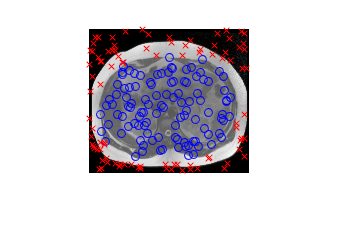

%Obtain indices of the 200 random points from the last iteration where the segmentation is 1/0
randPermTrue = randPerm(ImSegm(randPerm) == 1);
randPermFalse = randPerm(ImSegm(randPerm) == 0);
%Plot the points on the image
figure();
imshow(data3.trainingImage)
hold on;
plot(idivide(int16(randPermTrue), size(data3.trainingImage, 1)), mod(randPermTrue, size(data3.trainingImage, 1)), 'ob')
plot(idivide(int16(randPermFalse), size(data3.trainingImage, 1)), mod(randPermFalse, size(data3.trainingImage, 1)), 'xr')

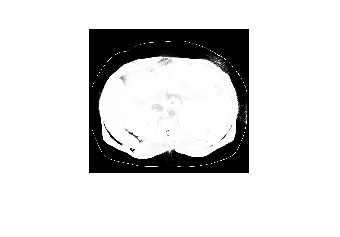

%Plot the posterior of the training image
figure();
imshow(Sigmoid(ImTrainRes), [])

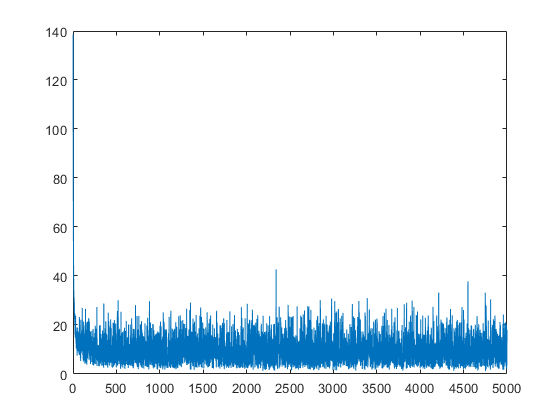

%Plot the progression of the cost vector throughout the iterations
figure();
plot(costVector);

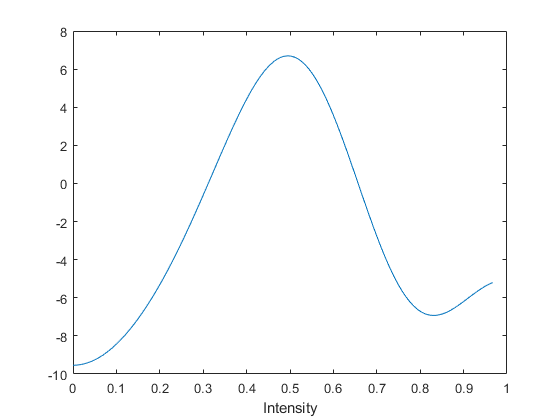

%Plot the value of a = sum(beta * basisFunction) across the intensity
%values
X = 0:0.001:max(ImTrain(:));
Y = Beta(1) * BasisFun(X, 1);
for i = 2:6
    Y = Y + Beta(i) * BasisFun(X, i);
end
figure();
plot(X,Y)
xlabel("Intensity")

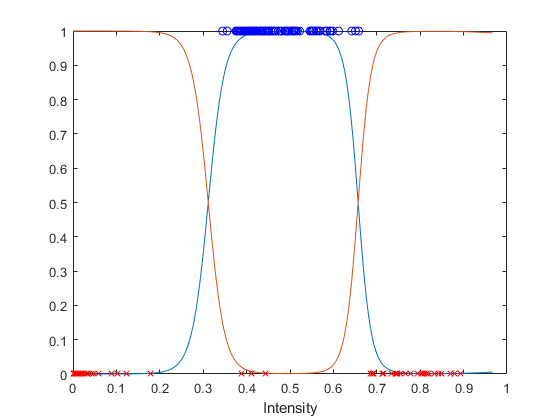

figure();
%Plot the squashed sigma(a) and add the selected points from the previous
%iteration
plot(X, Sigmoid(Y))
hold on;
plot(X, 1 - Sigmoid(Y))
plot(ImTrain(randPermTrue), 1, 'ob')
plot(ImTrain(randPermFalse), 0, 'xr')
xlabel("Intensity")
hold off;

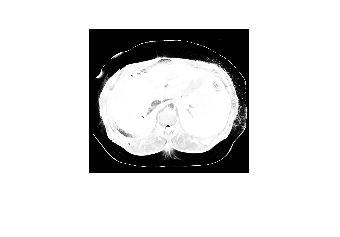

%Apply the model to the test image
ImTest = data3.testImage;
ImTestRes = zeros(size(ImTest));
for i = 1:6
    ImTestRes = ImTestRes + Beta(i) * BasisFun(ImTest, i);
end
ImTestRes = Sigmoid(ImTestRes);
imshow(ImTestRes)

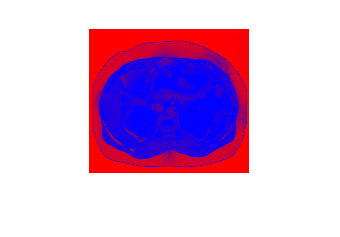

Blue = ImTestRes(ImTestRes > 0.5);
Red = ImTestRes(ImTestRes <= 0.5);
imfuse(Blue, Red);
%imshow(imfuse(Blue, Red, 'blend'))
rgb = zeros(size(ImTest));
rgb(:, :, 1) = 1 - ImTestRes;
rgb(:, :, 3) = ImTestRes;
%ImFused = imfuse(ImTestRes, 1 - ImTestRes, 'ColorChannels', [R G b]);
imshowpair(1 - ImTrainRes, ImTrainRes, 'ColorChannels', [1 0 2])

%Some random testing section


Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Error in BasisFun (line 4)
    B = cos(pi * (m - 1) * Im);

Related documentation